# Problemas de valor inicial

## Sistema de dos ecuaciones lineales de primer orden


$$y_1^{\prime } =-0\ldotp 5y_1$$
                        
$$y_1 \left(0\right)=4$$



$$y_2^{\prime } =4-0\ldotp 3y_2 -0\ldotp 1y_1$$
       
$$y_2 \left(0\right)=6$$


Grafica la solución entre t=0 y t=2.

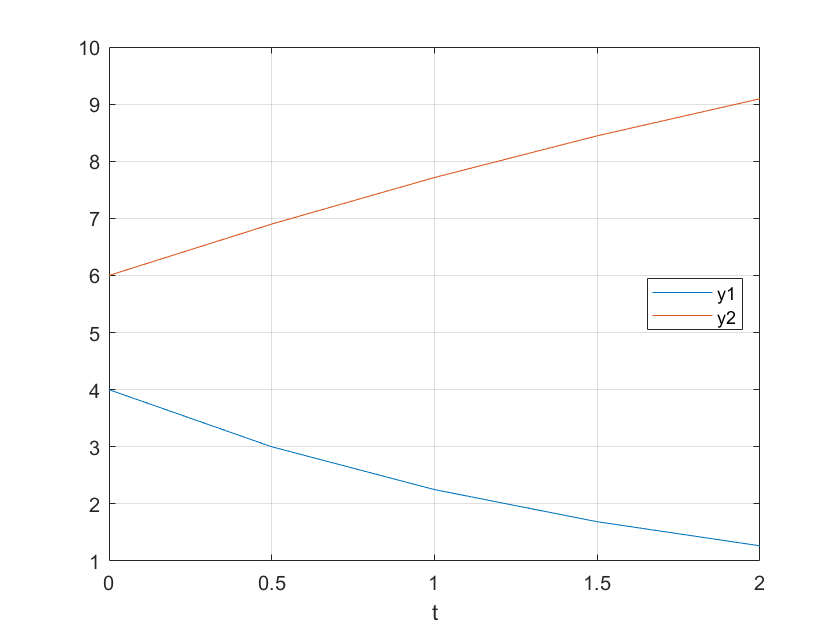

% y = [y1;y2]
% y' = [y1;y2]' = f(t, [y1;y2])
% y(0) = [y1(0); y2(0)]

f = @(t,y) [-0.5*y(1); 4 - 0.3*y(2) - 0.1*y(1)];
t0 = 0;
y0 = [4;6];
tf = 2;
h = 0.5;

[t,y] = ivpsV(f, y0, t0, tf, h, 'euler');
plot(t,y);
xlabel('t');
legend('y1','y2', 'location', 'best');
grid on;

## Sistema de dos ecuaciones lineales **homogeneas** de primer orden

### Matriz M de coeficientes (constantes)

#### Sistema 1

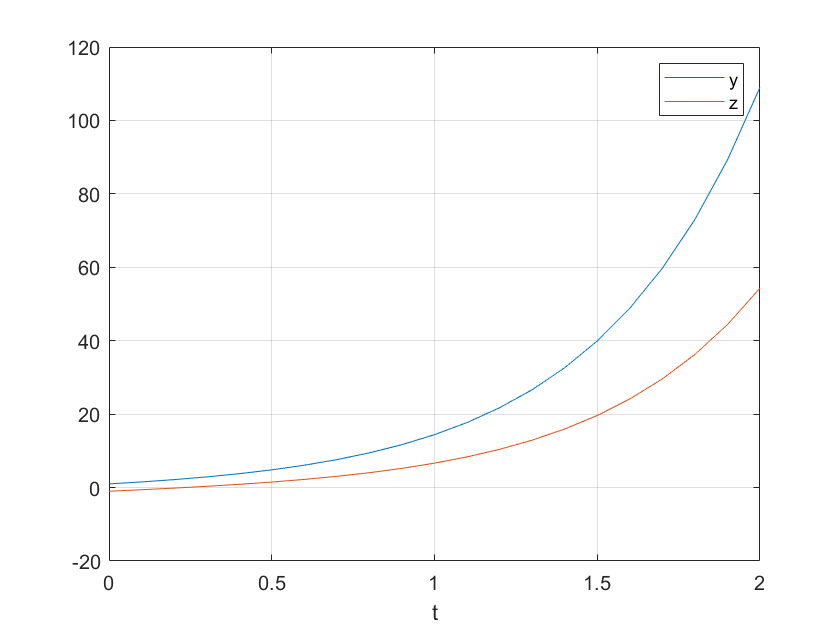

% y' = 3*y-2*z     y(0)=1
% z' = 2*y-2*z     z(0)=-1
% yz = [y;z]
% (yz)' = f(y,z)

M = [3,-2;2,-2];
t0 = 0;
yz0 = [1; -1];
tf = 2;
h = 0.1;
f = @(t,yz) M*yz;

[t,yz] = ivpsV(f, yz0, t0, tf, h, 'rk4');
plot(t,yz);
xlabel('t');
legend('y','z');
grid on;

Solución simbólica

syms y(t) z(t) yz(t)
yz(t) = [y;z];
odes = diff(yz) == M*yz;
[ySolG(t), zSolG(t)] = dsolve(odes)

$$ySolG(t) = \frac{C_{1}\,{\mathrm{e}}^{-t}}{2}+2\,C_{2}\,{\mathrm{e}}^{2\,t}$$

$$zSolG(t) = C_{1}\,{\mathrm{e}}^{-t}+C_{2}\,{\mathrm{e}}^{2\,t}$$

conds = yz(0) == yz0;
[ySolP(t), zSolP(t)] = dsolve(odes,conds)

$$ySolP(t) = 2\,{\mathrm{e}}^{2\,t}-{\mathrm{e}}^{-t}$$

$$zSolP(t) = {\mathrm{e}}^{2\,t}-2\,{\mathrm{e}}^{-t}$$

% yz(t) = [2;1]*exp(2*t) + [-1;-2]*exp(-t)

Valores y vectores propios de M

[V,D] = eig(M)   

V =     0.8944    0.4472
    0.4472    0.8944


D =      2     0
     0    -1


% real distinct eigenvalues: D(1,1)=2 and D(2,2)=-1  
% eigenvectors: V(:,1)=[0.8944;0.4472] and V(:,2)=[0.4472;0.8944]
% Solución general
% yzG = K1*V(:,1)*exp(D(1,1)*t)) + K2*V(:,2)*exp(D(2,2)*t))
% Solución particular : condición inicial en t=0
% yz(0) = K1*V(:,1) + K2*V(:,2) = V*[K1;K2] -> [K1;K2]= V\yz(0)
K = V\yz0

K =     2.2361
   -2.2361


K(1)*V(:,1)

ans =      2
     1


K(2)*V(:,2)

ans =    -1.0000
   -2.0000


#### Sistema 2

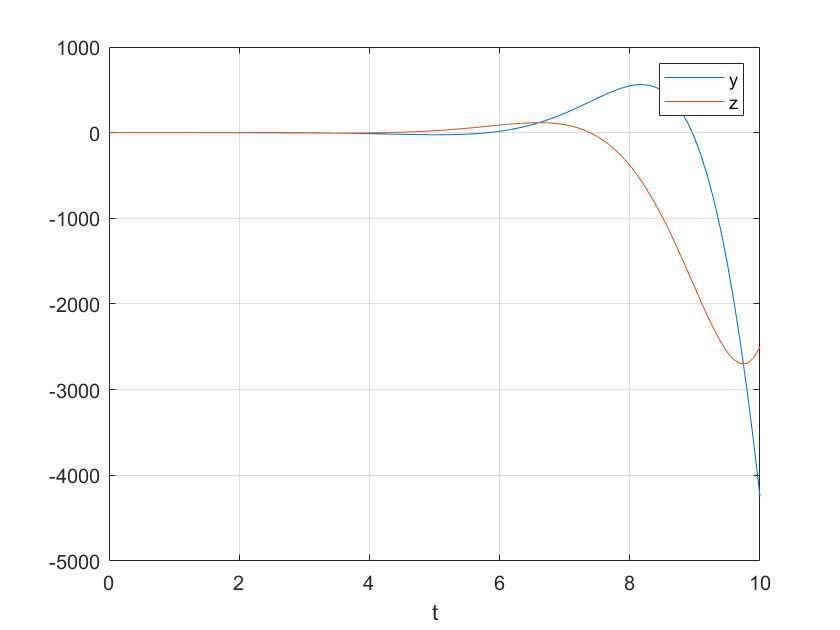

% y' =  y+z     y(0)=0.1
% z' = -y+z     z(0)=0.2
% tf = 10

M = [1,1;-1,1];
t0 = 0;
yz0 = [0.1; 0.2];
tf = 10;
h = 0.1;
f = @(t,yz) M*yz;

[t,yz] = ivpsV(f, yz0, t0, tf, h, 'rk4');
plot(t,yz);
xlabel('t');
legend('y','z');
grid on;

#### Sistema 3

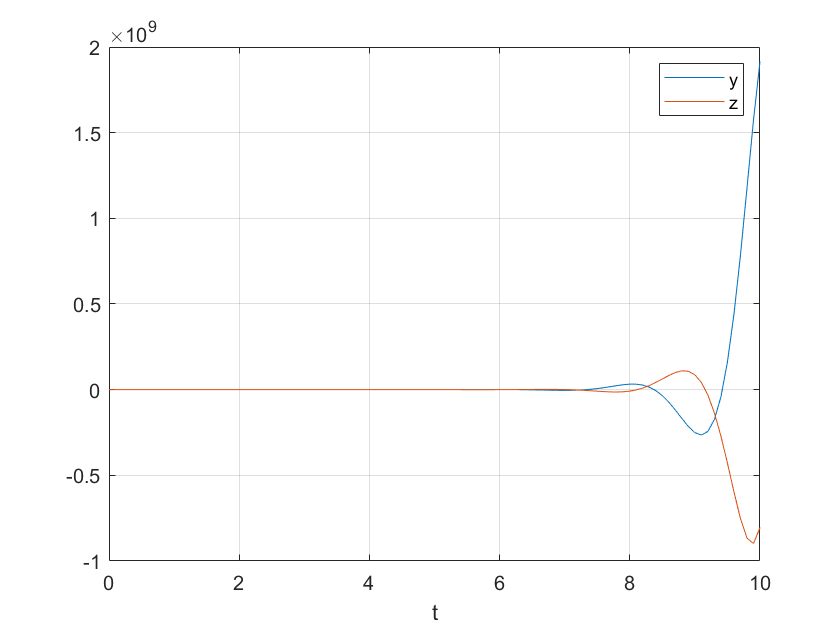

% y' = -y-6*z    y(0)=0
% z' = 3y+5*z    z(0)=2
% tf = 10

M = [-1,-6;3,5];
t0 = 0;
yz0 = [0; 2];
tf = 10;
h = 0.1;
f = @(t,yz) M*yz;

[t,yz] = ivpsV(f, yz0, t0, tf, h, 'rk4');
plot(t,yz);
xlabel('t');
legend('y','z');
grid on;

#### Sistema 4

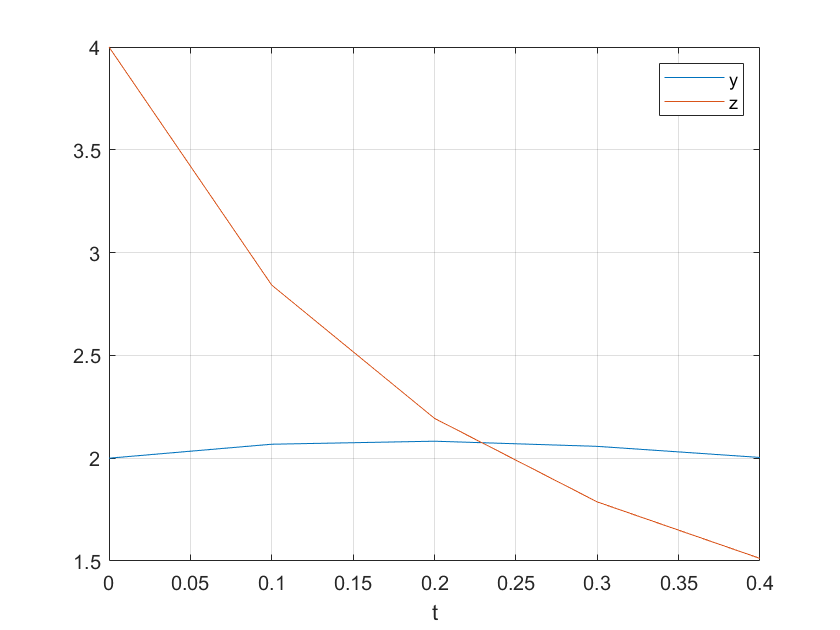

% y' = -2*y + 5*exp(-t)
% z' = -(y*z^2)/2;
% yz(0) = [2; 4];
% tf = 0.4

t0 = 0;
yz0 = [2; 4];
tf = 0.4;
h = 0.1;
f = @(t,y) [-2*y(1)+5*exp(-t); -(y(1)*(y(2).^2))/2];

[t,y] = ivpsV(f, yz0, t0, tf, h, 'rk4');
plot(t,y);
xlabel('t');
legend('y','z');
grid on;

#### Sistema 5

Pb 25.26 Chapra

Suponga que un proyectil se lanza hacia arriba desde la superficie de la Tierra. Se acepta que la única fuerza que actúa sobre el objeto es la fuerza de la gravedad, hacia abajo. En estas condiciones, se usa un balance de fuerza para obtener,


$$v^{\prime } =-g\frac{R^2 }{{\left(R+y\right)}^2 }$$


donde v = velocidad hacia arriba (m/s), t = tiempo (s), y = altitud (m) medida hacia arriba a partir de la superficie terrestre, g =aceleración gravitacional a la superficie terrestre (≈9.81 m/$s^2$), y R = radio de la tierra (≈6.37 × ${10}^6$ m). Determine la altura máxima que se obtendría si v(t = 0) = 1 400 m/s.

% y' = v ---> y(1)'=y(2)
% y(2)'=-g*R.^2 / (R+y(1))^2
g = 9.81;
R = 6.37e6;

t0 = 0;
yz0 = [0; 1400];
tf = 5;
h = 0.1;
f = @(t,y) [y(2);-g*R.^2 / (R+y(1)).^2];

[t,y] = ivpsV(f, yz0, t0, tf, h, 'rk4');

%Maximo de distancia alcanzado
max(y(1,:))                                                                                  

ans = 6.8775e+03

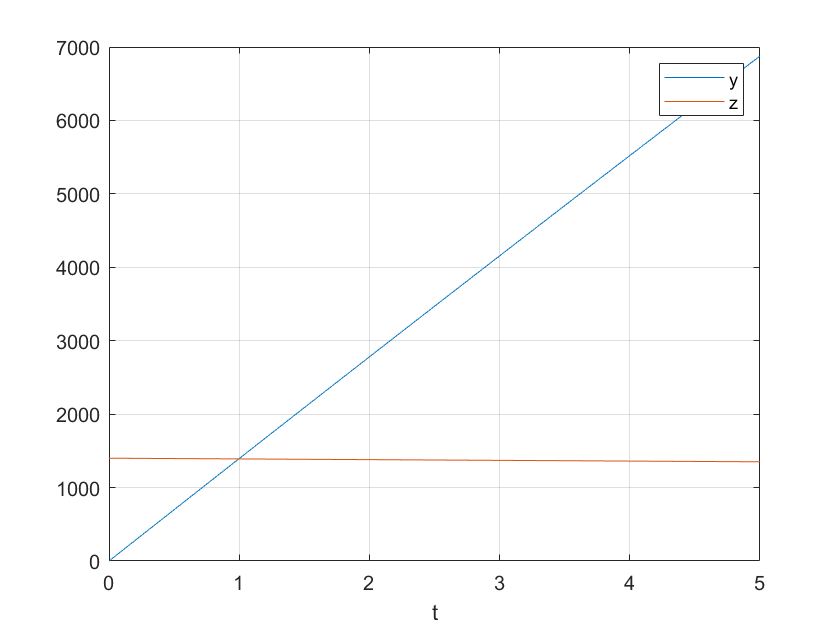

plot(t,y);
xlabel('t');
legend('y','z');
grid on;

## Ecuación diferencial lineal homogenea de segundo orden

Con coeficientes constantes


$$y^{\textrm{''}} +ay^{\prime } +\textrm{by}=0$$


Se convierte a un sistema de dos ecuaciones diferenciales de primer orden definiendo una nueva variable $z=y^{\prime }$


$$\begin{array}{l}
y^{\prime } =z\\
z^{\prime } =y^{\textrm{''}} =-a\;z-b\;y
\end{array}$$



$${\left\lbrack \begin{array}{c}
y\\
z
\end{array}\right\rbrack }^{\prime } =\left\lbrack \begin{array}{cc}
0 & 1\\
-b & -a
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y\\
z
\end{array}\right\rbrack$$


#### Segundo orden 1

$y^{\prime \prime } +y^{\prime } -2y=0$         $y\left(0\right)=3$, $y^{\prime } \left(0\right)=0$

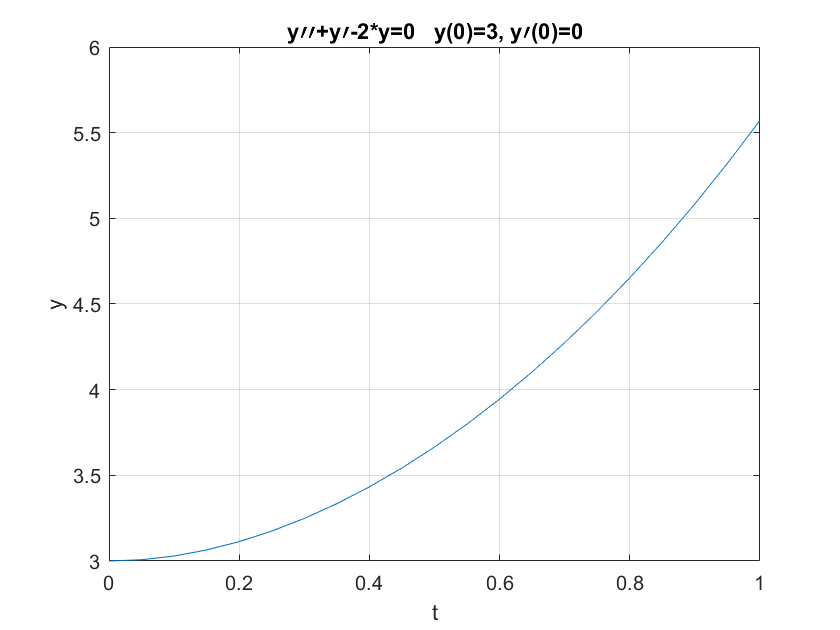

% y'' = -y'+ 2*y
% y' = z
% z' = y'' = -z + 2*y
% yz = [y;z]
M = [0,1;2,-1];
yz0 = [3; 0];
t0 = 0;
tf = 1;
h = 0.05;

f = @(t,yz) M*yz;
[t,yz] = ivpsV(f, yz0, t0, tf, h, 'rk4');
plot(t,yz(1,:));
title('y\prime\prime+y\prime-2*y=0   y(0)=3, y\prime(0)=0');
xlabel('t');
ylabel('y');
grid on;

syms y(t)
ode = diff(y,t,2)+diff(y,t,1)-2*y == 0;
yG = dsolve(ode);
yz0 = [3; 0];
cond1 = y(0) == yz0(1); 
Dy = diff(y);
cond2 = Dy(0) == yz0(2); 
conds = [cond1 cond2];
yP = dsolve(ode, conds)

$$yP = {\mathrm{e}}^{-2\,t}+2\,{\mathrm{e}}^{t}$$

syms y(t) z(t) yz(t)
yz(t) = [y;z];
odes = diff(yz) == M*yz;
[ySolG(t), zSolG(t)] = dsolve(odes);
conds = yz(0) == yz0;
[ySolP(t), zSolP(t)] = dsolve(odes,conds)

$$ySolP(t) = {\mathrm{e}}^{-2\,t}+2\,{\mathrm{e}}^{t}$$

$$zSolP(t) = 2\,{\mathrm{e}}^{t}-2\,{\mathrm{e}}^{-2\,t}$$

p = [1,1,-2];
roots(p)

ans =     -2
     1


[V,D] = eig(M) 

V =     0.7071   -0.4472
    0.7071    0.8944


D =      1     0
     0    -2


K = V\yz0;
K(1)*V(:,1)

ans =      2
     2


K(2)*V(:,2)

ans =      1
    -2


#### Segundo orden 2

$y^{\prime \prime } -y^{\prime } -2y=0$         $y\left(0\right)=0\ldotp 1$, $y^{\prime } \left(0\right)=0\ldotp 2$

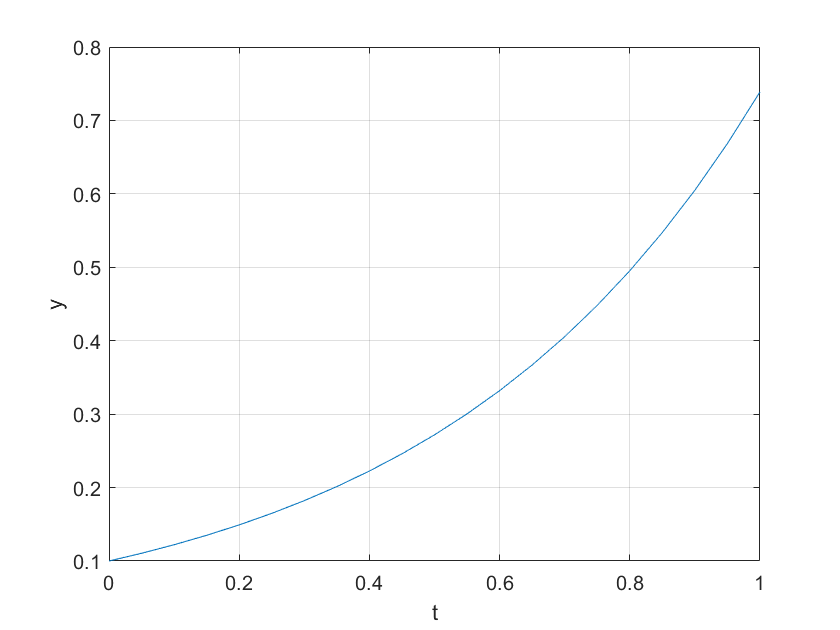

% y'' = +y'+ 2*y
% y' = z
% z' = y'' = z + 2*y
% yz = [y;z]
% tf = 1;
M = [0,1;2,1];
yz0 = [0.1; 0.2];
t0 = 0;
tf = 1;
h = 0.05;

f = @(t,yz) M*yz;
[t,yz] = ivpsV(f, yz0, t0, tf, h, 'rk4');
plot(t,yz(1,:));
xlabel('t');
ylabel('y');
grid on;

#### Segundo orden 3

$y^{\prime \prime } +y^{\prime } -6y=0$         $y\left(0\right)=5$, $y^{\prime } \left(0\right)=0$

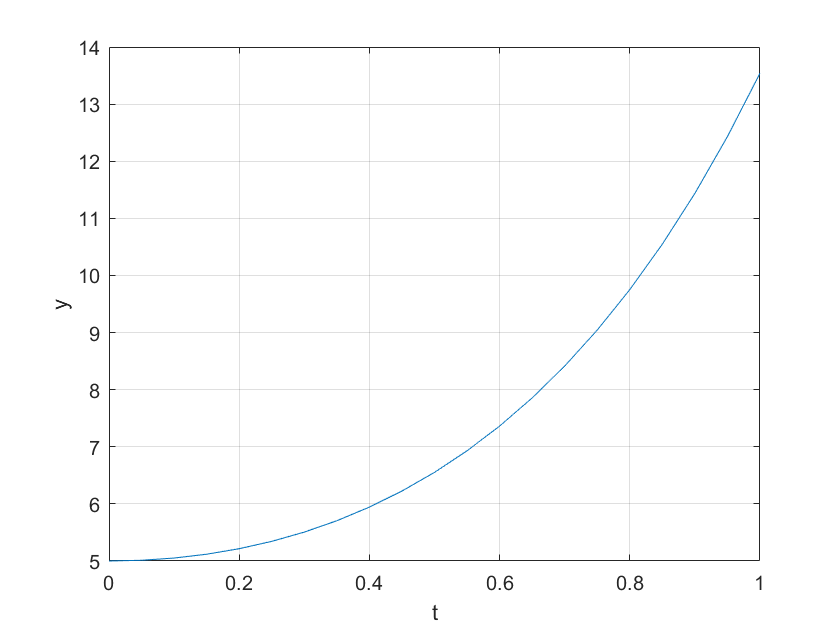

% y'' = -y'+ 6*y
% y' = z
% z' = y'' = -z + 6*y
% yz = [y;z]
% tf = 1;
M = [0,1;2,1];
yz0 = [5; 0];
t0 = 0;
tf = 1;
h = 0.05;

f = @(t,yz) M*yz;
[t,yz] = ivpsV(f, yz0, t0, tf, h, 'rk4');
plot(t,yz(1,:));
xlabel('t');
ylabel('y');
grid on;

#### Segundo orden 4

Harmonic oscillator

$y^{\prime \prime } +y=0$         $y\left(0\right)=4$, $y^{\prime } \left(0\right)=0$

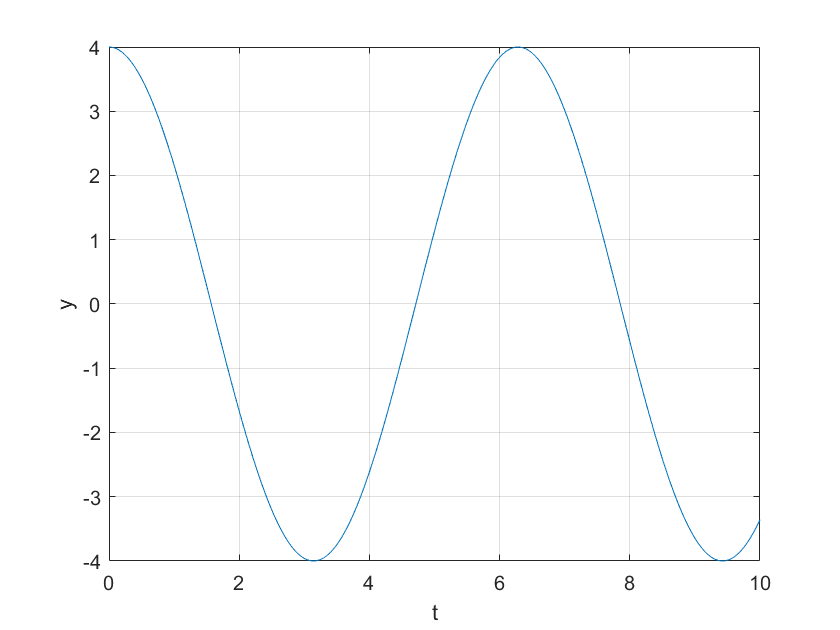

% y'' = -y
% y' = z
% z' = y'' = -y
% yz = [y;z]
% tf = 10;

M = [0,1;-1,0];
yz0 = [4; 0];
t0 = 0;
tf = 10;
h = 0.05;

f = @(t,yz) M*yz;
[t,yz] = ivpsV(f, yz0, t0, tf, h, 'rk4');
plot(t,yz(1,:));
xlabel('t');
ylabel('y');
grid on;

#### Segundo orden 5

Motion of a mass connected to a spring, with viscous friction on the surface and an applied external force.

${3y}^{\prime \prime } +{18y}^{\prime } +102y=10$         $y\left(0\right)=0$, $y^{\prime } \left(0\right)=0$

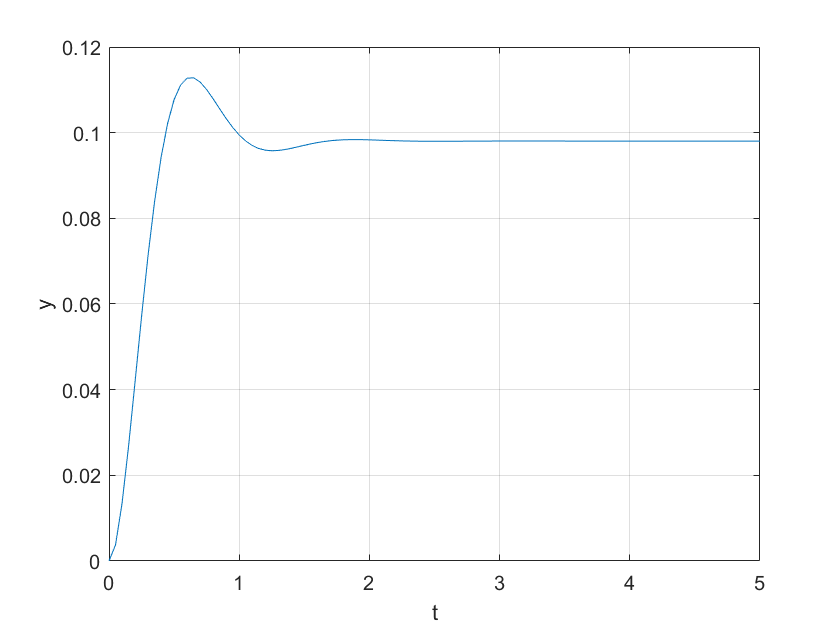

% y'' = (-y'*18- 102*y + 10)/3
% y' = z
% z' = y'' = (-z*18- 102*y + 10)/3
% yz = [y;z]
% tf = 5;
yz0 = [0; 0];
t0 = 0;
tf = 5;
h = 0.05;

f = @(t,yz) [yz(2);(-yz(2)*18 - 102*yz(1) + 10)/3];
[t,yz] = ivpsV(f, yz0, t0, tf, h, 'rk4');
plot(t,yz(1,:));
xlabel('t');
ylabel('y');
grid on;

#### Segundo orden 6

Resuelve el problema siguiente de t=0 a 5.

$y^{\prime \prime } +{0\ldotp 6y}^{\prime } +8y=0$         $y\left(0\right)=4$, $y^{\prime } \left(0\right)=0$

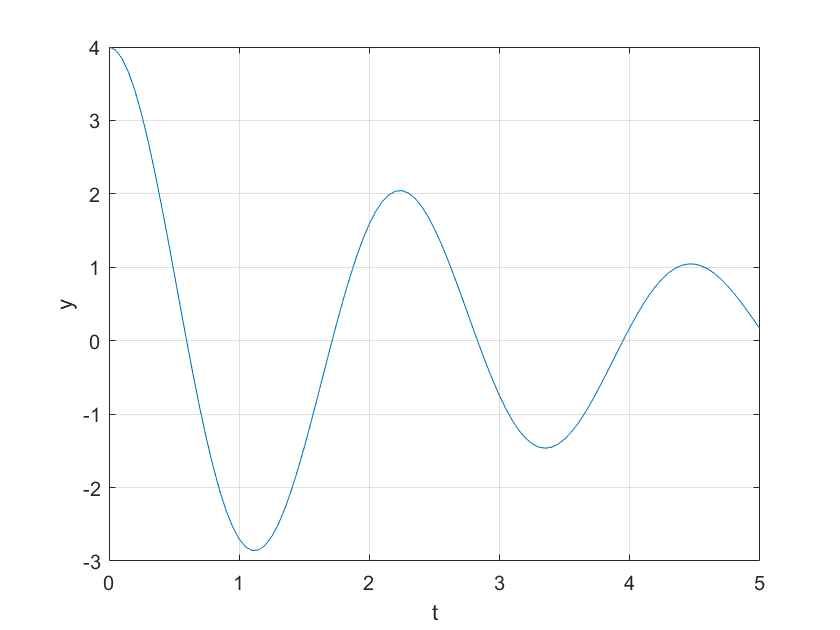

% y'' = -0.6y' - 8y
% y' = z
% z' = y'' = -8y - 0.6z
% yz = [y;z]
% tf = 5;

M = [0,1;-8,-0.6];
yz0 = [4; 0];
t0 = 0;
tf = 5;
h = 0.05;

f = @(t,yz) M*yz;
[t,yz] = ivpsV(f, yz0, t0, tf, h, 'rk4');
plot(t,yz(1,:));
xlabel('t');
ylabel('y');
grid on;

#### Segundo orden 7

Se trata del oscilador de van der Pol (con amortiguamiento no lineal)


$$\frac{d^2 }{\mathrm{d}t^2 }y-\left(1-y^2 \right)\frac{\mathrm{d}}{\mathrm{d}t}y+y=0$$
          
$$y\left(0\right)=y^{\prime } \left(0\right)=1$$


Grafica la solución entre t=0 y t=10.

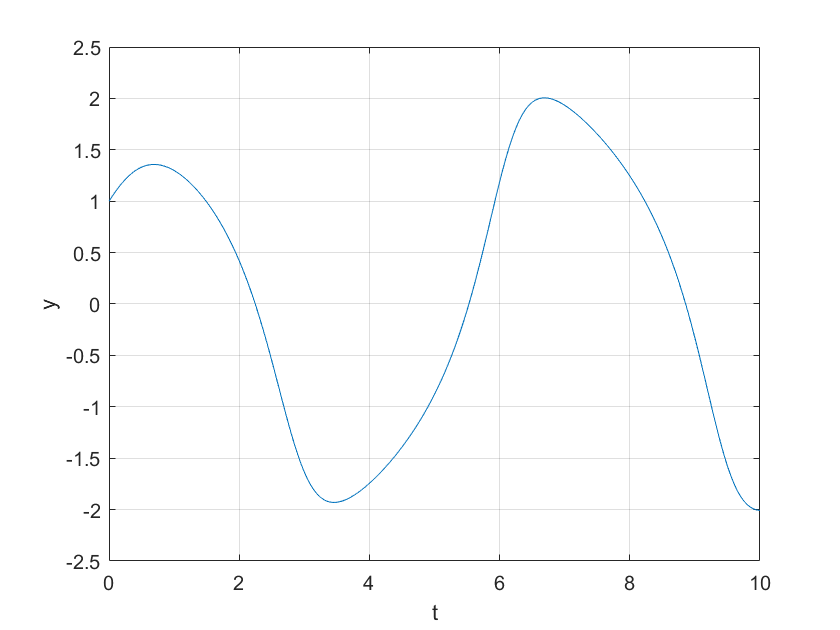

% y'' = +(1-y^2)*y'-y
% y' = z
% z' = y'' = +(1-y^2)*z-y
% yz = [y;z]
% tf = 10;
yz0 = [1;1];
t0 = 0;
tf = 10;
h = 0.05;

f = @(t,yz) [yz(2);+(1-yz(1).^2)*yz(2)-yz(1)];
[t,yz] = ivpsV(f, yz0, t0, tf, h, 'rk4');

plot(t,yz(1,:));

xlabel('t');
ylabel('y');
grid on;

function [x,y] = ivpsV( f, y0, x0, xf, h, method)
    x= x0:h:xf;
    n=length(x);
    m = length(y0);
    y=zeros(m,n);
    y(:,1)=y0;
    
    for i=1:1:n-1
        switch method
        case 'euler'
            phi=f(x(i),y(:,i));
            y(:,i+1)=y(:,i)+phi*h;
        case 'midpoint'
            ymid=y(i)+f(x(i),y(:,i))*h/2;
            phi=f(x(i)+h/2,ymid);
            y(:,i+1)=y(:,i)+phi*h;
        case 'heun'
            s1=f(x(i),y(:,i));
            predictor=y(:,i)+s1*h;
            s2= f(x(i+1), predictor);
            phi = (s1+s2)/2;
            y(:,i+1)=y(:,i)+phi*h;
        case 'rk4'
            k1=f(x(i),y(:,i));
            k2=f(x(i)+h/2,y(:,i)+k1*h/2);
            k3=f(x(i)+h/2,y(:,i)+k2*h/2);
            k4=f(x(i)+h, y(:,i)+k3*h);
            y(:,i+1)=y(:,i)+(k1+2*k2+2*k3+k4)*h/6;
        end
    end
end